# ELL7420 Design Assignment 2 - Pitch detection by autocorrelation

My time-domain method, explained alongside the MATLAB code. Run this Live Script with the speech samples folder beside it. The results folder will contain four CSV files and six plots.

The complete assignment needs a time-domain method and a frequency-domain method. This file covers my autocorrelation part. Once the second method is ready, we can compare both on the same samples.

## 1. The data and where the results go

I have four speech files: s1.wav, s2.wav, s3.wav and s4.wav. The p1.mat and p2.mat files give reference pitch values for s1 and s2 every 10 ms. A zero in the reference means unvoiced or silence. There are no reference pitch files for s3 and s4.

The code checks both speech samples and speech_samples next to this Live Script and one level up. It also checks for an extra nested folder created by a ZIP extractor. If it still cannot find s1.wav, MATLAB opens a folder picker: I select the folder that directly contains the WAV files. The code then prepares results/report_plots for saved figures.

%% ELL7420 Design Assignment 2: Pitch detection by autocorrelation
% This is the time-domain part of our pitch detection assignment.
% Run this file with the 'speech samples' folder beside it. It reads s1-s4,
% checks s1 and s2 against the given pitch values, and saves the plots/CSV files.

%% 1. Find the recordings and prepare the results folder
base = fileparts(mfilename('fullpath'));
% Check the common folder names next to the Live Script and one level up.
parents = {base, fullfile(base,'..')};
names = {'speech samples','speech_samples'};
data = '';
for p = 1:numel(parents)
    for n = 1:numel(names)
        folder = fullfile(parents{p},names{n});
        options = {folder,fullfile(folder,'speech_samples'), ...
                   fullfile(folder,'speech samples')};
        for q = 1:numel(options)
            if isfile(fullfile(options{q},'s1.wav'))
                data = options{q};
                break;
            end
        end
        if ~isempty(data), break; end
    end
    if ~isempty(data), break; end
end
if isempty(data)
    % If the folder is elsewhere, select the folder that has s1.wav inside.
    data = uigetdir(base,'Select the folder containing s1.wav');
    assert(~isequal(data,0),'No speech samples folder was selected');
end
assert(isfile(fullfile(data,'s1.wav')), ...
       'Please select the folder that directly contains s1.wav');
fprintf('Reading speech files from: %s\n',data);

Reading speech files from: C:\Users\pruth\Documents\Mtech\1st SEM\ADSP\Assignment_2\speech_samples


out = fullfile(base,'results');
plots = fullfile(out,'report_plots');
if ~isfolder(plots), mkdir(plots); end

## 2. Read the four recordings and estimate pitch

I use audioread to get the samples x and the sampling rate fs. If the file has two audio channels, I average them to get one signal. Then track_pitch moves along the speech and produces one estimate every 10 ms.

For s1 and s2 I load the given reference, count the voiced decisions, and calculate the pitch error where both tracks say voiced. For s3 and s4 I save the estimated track without reporting accuracy, because I do not have their true pitch.

The CSV files contain time_s, estimated_hz and reference_hz. The reference column is NaN for s3 and s4. The figures are saved in the order I would use them while explaining the method.

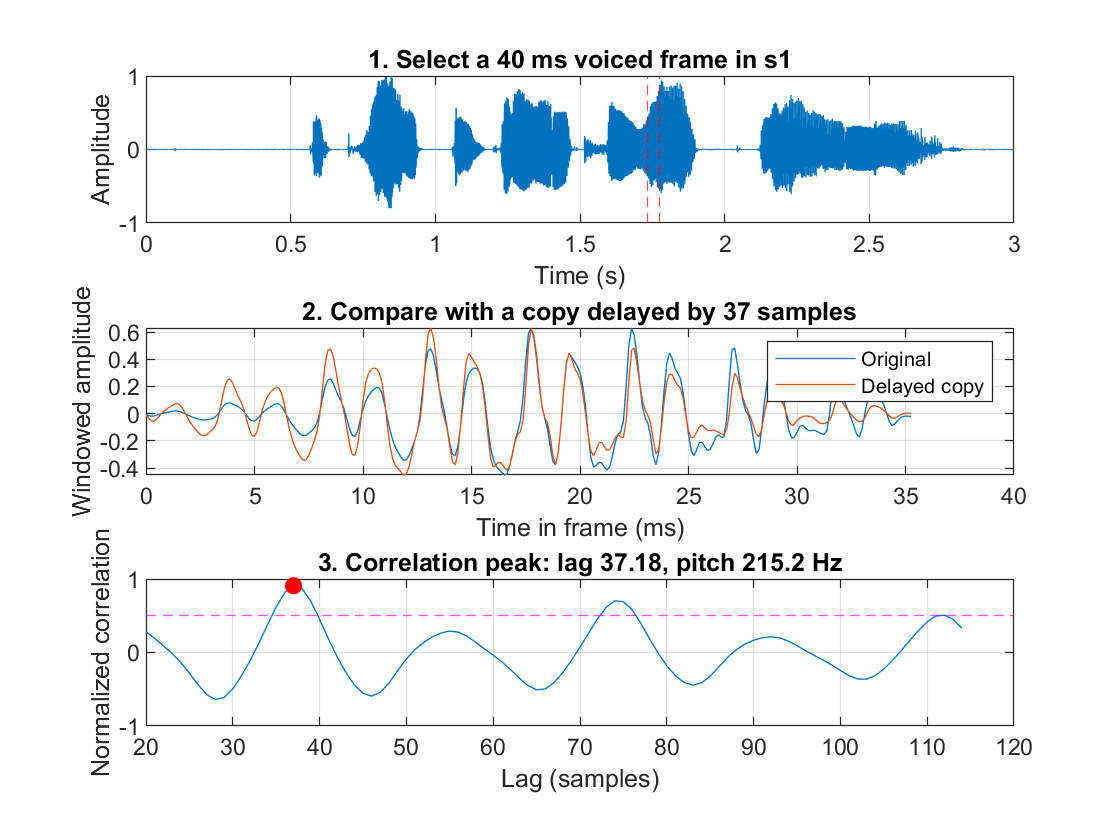

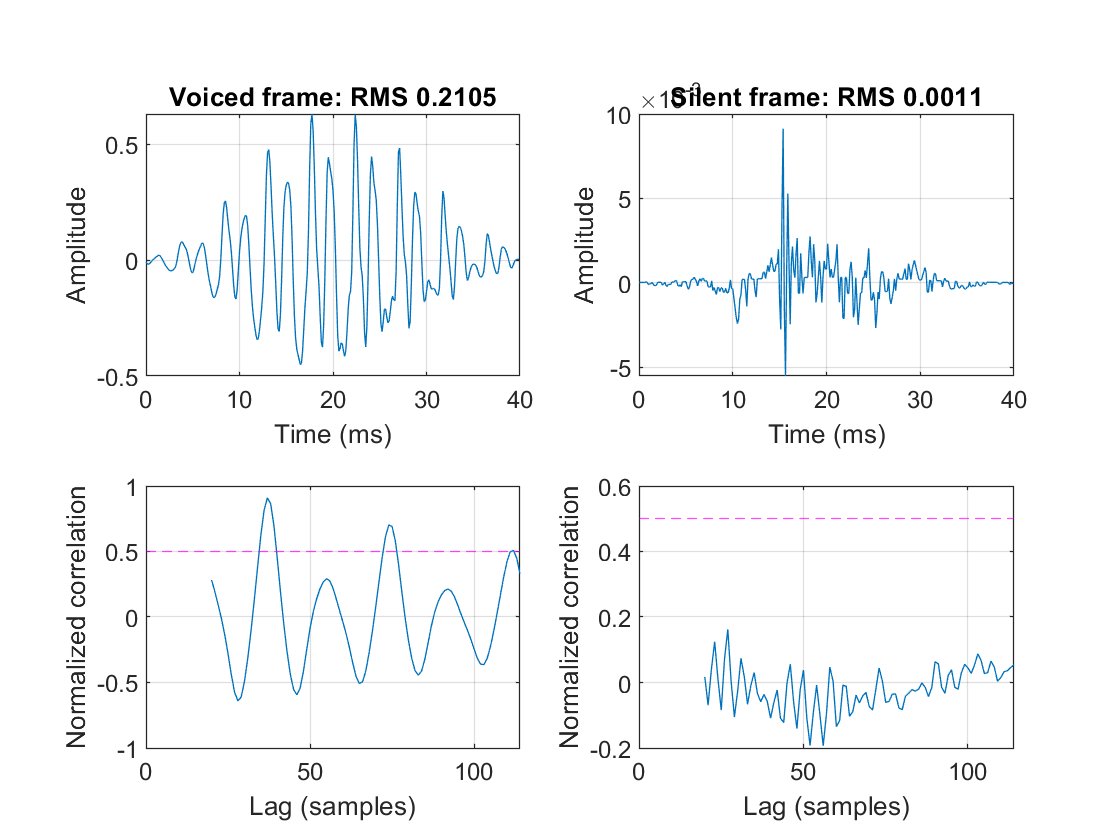

s1: TP=147 FP=13 FN=9 TN=131 | precision=91.9% recall=94.2% | voiced MAE=7.16 Hz | within 20%=143/156


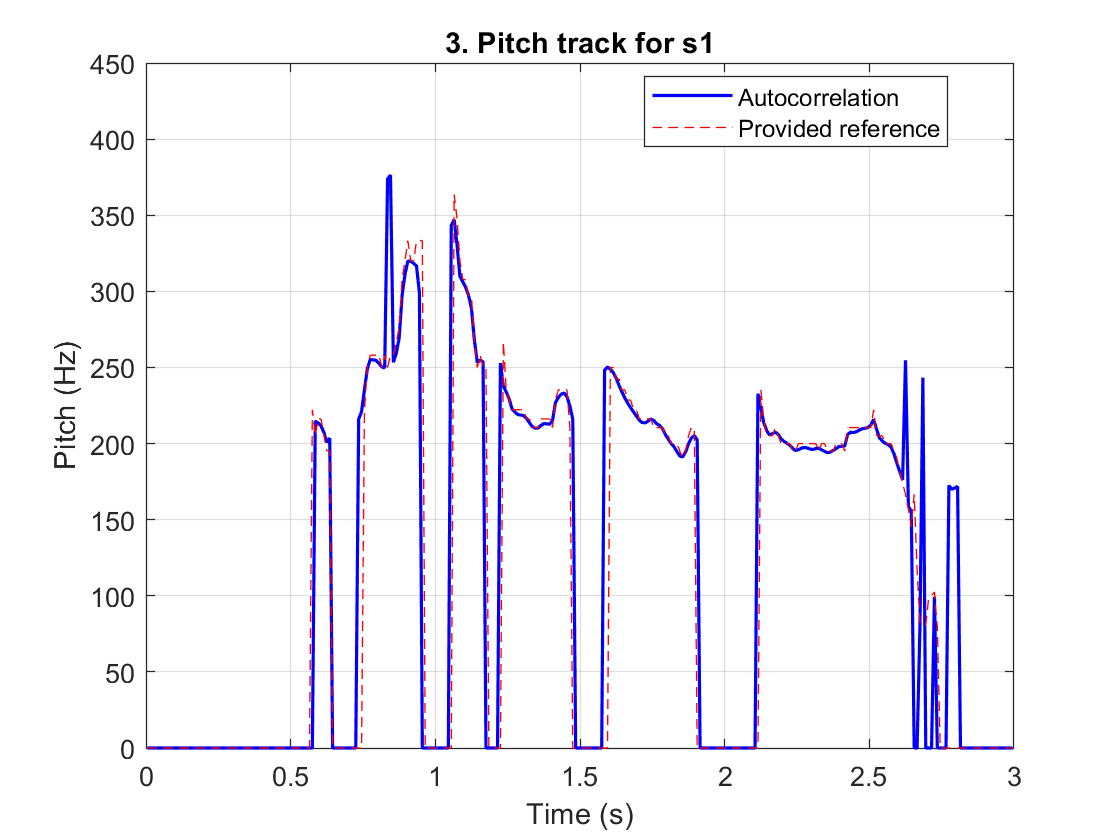

s2: TP=160 FP=2 FN=15 TN=123 | precision=98.8% recall=91.4% | voiced MAE=5.69 Hz | within 20%=156/175


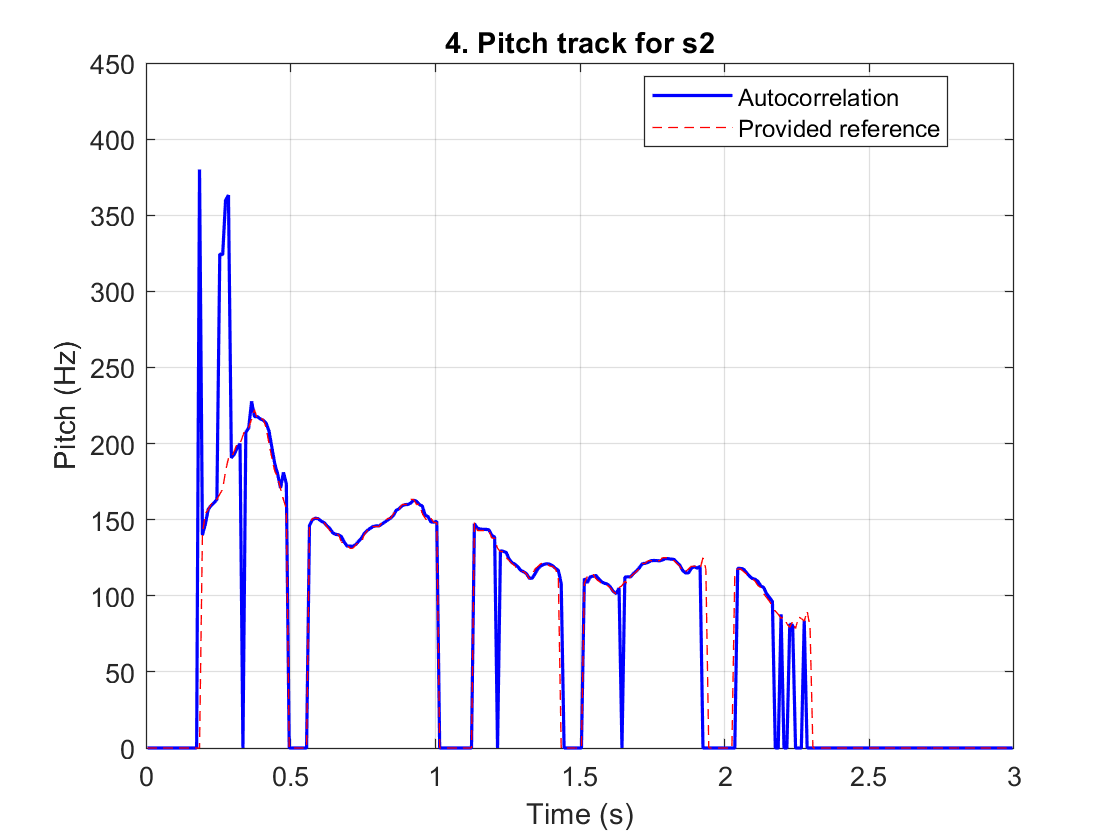

s3: 174 voiced of 300 frames; no reference supplied


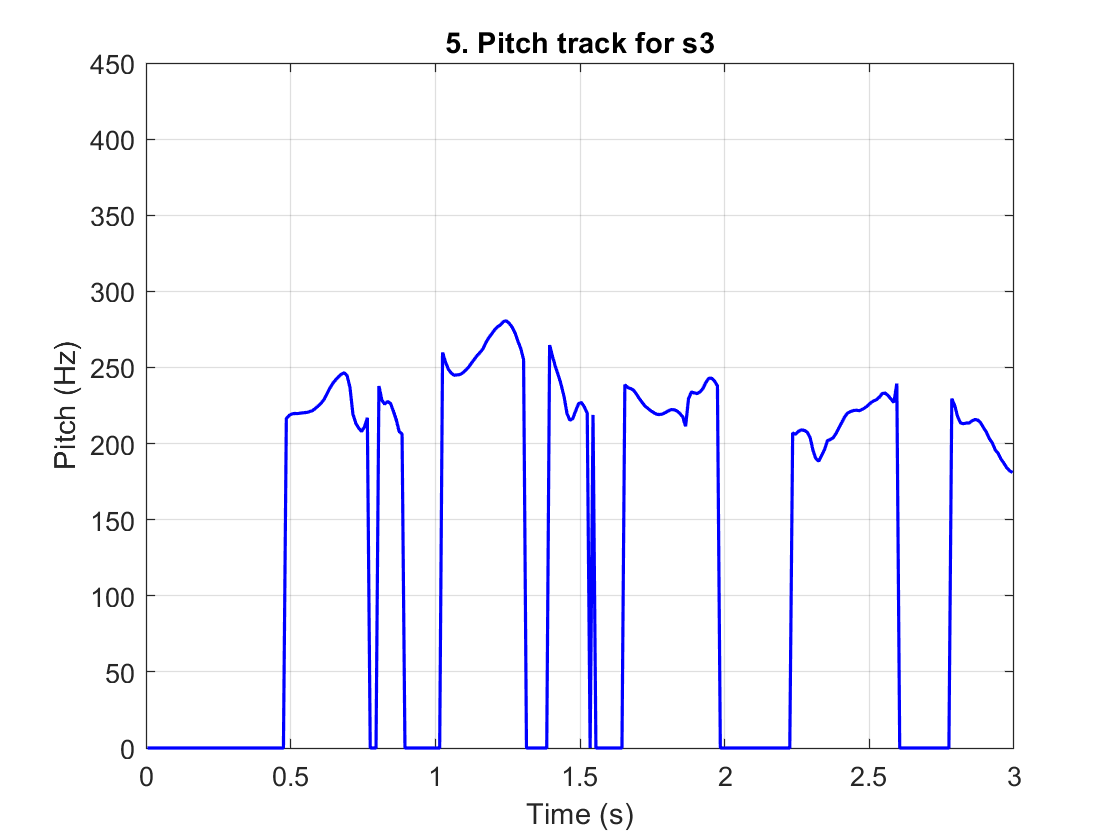

s4: 141 voiced of 300 frames; no reference supplied


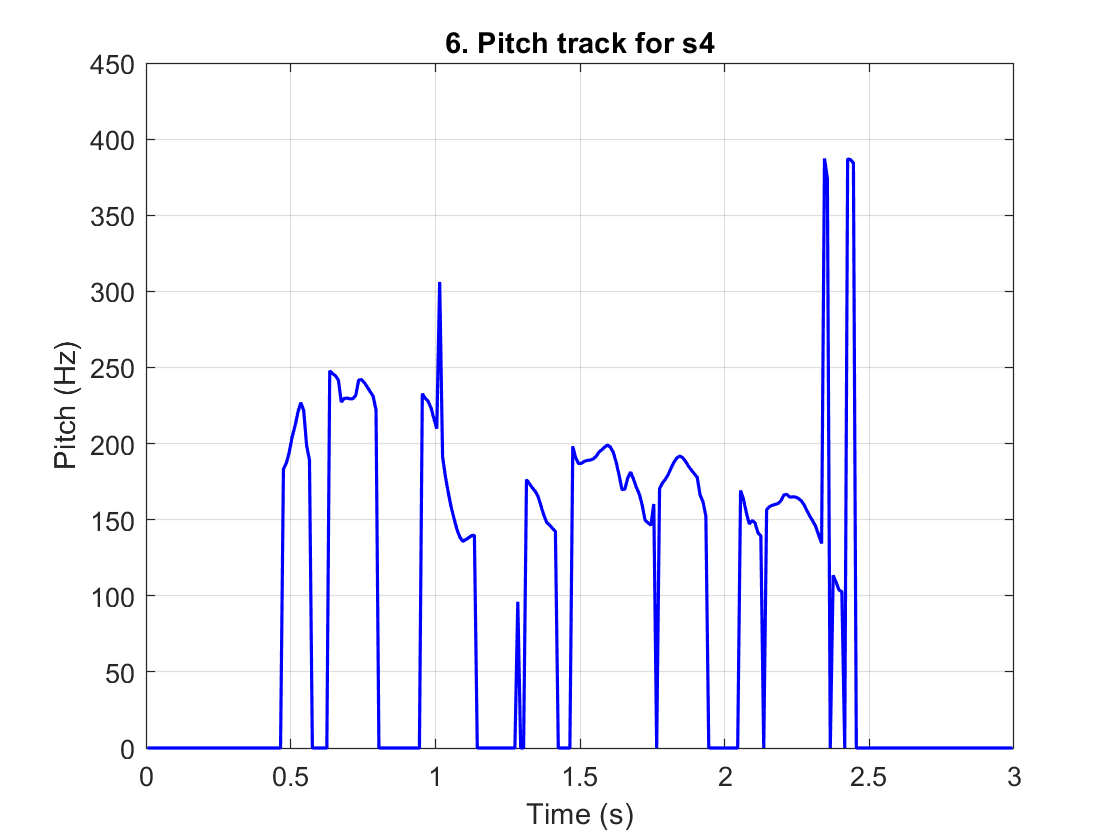

%% 2. Estimate pitch for each speech sample
for s = 1:4
    [x,fs] = audioread(fullfile(data,sprintf('s%d.wav',s)));
    x = mean(x,2); % Average channels if the recording is stereo.
    if s == 1, show_method(x,fs,plots); end
    [time,pitch] = track_pitch(x,fs);
    reference = nan(size(pitch));

    % Only s1 and s2 have a supplied pitch track. Zero means unvoiced.
    if s <= 2
        key = sprintf('p%d',s);
        saved = load(fullfile(data,[key '.mat']));
        reference = saved.(key); reference = reference(:);
        assert(numel(reference)==numel(pitch),'Reference length does not match');
        actual = reference > 0; detected = pitch > 0;
        tp = sum(actual & detected); fp = sum(~actual & detected);
        fn = sum(actual & ~detected); tn = sum(~actual & ~detected);
        matched = actual & detected; % Compare pitch error where both say voiced.
        mae = mean(abs(pitch(matched)-reference(matched)));
        within20 = sum(abs(pitch(matched)-reference(matched)) <= ...
                       .2*reference(matched));
        fprintf(['s%d: TP=%d FP=%d FN=%d TN=%d | precision=%.1f%% ' ...
                 'recall=%.1f%% | voiced MAE=%.2f Hz | within 20%%=%d/%d\n'], ...
                 s,tp,fp,fn,tn,100*tp/max(tp+fp,1), ...
                 100*tp/max(tp+fn,1),mae,within20,sum(actual));
    else
        % There is no ground truth for s3/s4, so we can only report our estimates.
        fprintf('s%d: %d voiced of %d frames; no reference supplied\n', ...
                s,sum(pitch>0),numel(pitch));
    end

    % 3. Save frame-wise values and the pitch track.
    % The reference column is NaN for s3/s4 because no reference was given.
    tableOut = table(time,pitch,reference,'VariableNames', ...
                     {'time_s','estimated_hz','reference_hz'});
    writetable(tableOut,fullfile(out,sprintf('s%d_autocorrelation.csv',s)));
    fig = figure('Color','w','Name',sprintf('%d. s%d pitch track',s+2,s));
    plot(time,pitch,'b','LineWidth',1.2); hold on;
    if s <= 2
        plot(time,reference,'r--');
        legend('Autocorrelation','Provided reference','Location','best');
    end
    xlabel('Time (s)'); ylabel('Pitch (Hz)');
    title(sprintf('%d. Pitch track for s%d',s+2,s));
    xlim([0 numel(x)/fs]); ylim([0 450]); grid on;
    saveas(fig,fullfile(plots,sprintf('%02d_s%d_pitch_track.png',s+2,s)));
end

## 3. What the pitch tracking function does

I take a 40 ms frame for each point on a 10 ms grid. Overlapping frames give enough speech to see a repeating pattern while the answer still updates often. A frame starts at 0 Hz and receives a pitch only if it passes both checks.

The first check is RMS amplitude at least 0.008, so a very quiet frame is left unvoiced. The second check is a selected correlation peak of at least 0.50. These are the thresholds used in my code; they are not universal settings for every speaker.

function [time,pitch] = track_pitch(x,fs)
    % Work every 10 ms so our estimates line up with p1/p2.
    % Use 0 Hz when a frame does not pass the voiced tests.
    hop = round(.01*fs);
    count = ceil(numel(x)/hop);
    time = ((0:count-1)'*hop+floor(hop/2))/fs;
    pitch = zeros(count,1);
    for i = 1:count
        [~,lags,r,energy] = frame_correlation(x,fs,i);
        if energy < .008, continue; end % Too quiet to give a useful pitch.
        [period,strength] = best_period(lags,r);
        % A regular speech cycle should give a strong correlation peak.
        if strength >= .50, pitch(i) = fs/period; end
    end
end

## 4. Prepare one frame and compare delayed copies

I centre the 40 ms frame at the current time point and pad with zeros at the start or end of the recording if needed. I subtract the mean to remove a constant offset, then apply a Hamming window to reduce the effect of the frame edges.

Autocorrelation asks: how well does this frame match a delayed version of itself? At lag k, I multiply the overlapping samples from the original and delayed copies, add those products, and divide by the energies of both copies. Normalising helps stop amplitude alone from controlling the match.

I search lags corresponding approximately to 70-400 Hz. If a repeated speech cycle is present, its period should give a strong peak in this range. The RMS value also tells me whether the frame is too quiet to trust.

function [frame,lags,r,energy] = frame_correlation(x,fs,i)
    % Take 40 ms around this frame's time point, padding at the ends.
    L = round(.04*fs); hop = round(.01*fs);
    index = (i-1)*hop+floor(hop/2)-floor(L/2)+(0:L-1)';
    valid = index>=0 & index<numel(x);
    frame = zeros(L,1); frame(valid) = x(index(valid)+1);
    % Remove the mean and taper the edges before comparing delayed copies.
    window = .54-.46*cos(2*pi*(0:L-1)'/(L-1));
    frame = (frame-mean(frame)).*window;
    energy = sqrt(mean(frame.^2));
    % Pitch = fs/lag, so these lags cover roughly 70 to 400 Hz.
    lags = (ceil(fs/400):min(L-2,floor(fs/70)))';
    r = zeros(size(lags));
    for j = 1:numel(lags)
        k = lags(j); a = frame(1:end-k); b = frame(k+1:end);
        % Normalise so loudness has less effect on the peak height.
        r(j) = sum(a.*b)/sqrt(sum(a.^2)*sum(b.^2)+1e-12);
    end
end

## 5. Pick the period and turn it into Hz

A correlation curve can peak at one period and at multiples of that period. I find the local peaks and take the earliest peak that reaches at least 82% of the strongest local peak. This favours a short convincing period.

The peak might fall between two sample positions, so I use its neighbouring correlation values for a small parabolic adjustment. I limit that adjustment to half a sample. The pitch is then fs divided by the adjusted period in samples.

The voiced example used in the first figure had an adjusted lag of about 37.18 samples, which gave about 215.2 Hz. This describes one frame of s1, not a pitch for the whole recording.

function [period,strength] = best_period(lags,r)
    % Find local peaks, then take the first one close to the strongest peak.
    % This favours the shortest convincing period over its multiples.
    peaks = find(r(2:end-1)>r(1:end-2) & r(2:end-1)>=r(3:end))+1;
    period = NaN; strength = 0;
    if isempty(peaks), return; end
    peaks = peaks(r(peaks)>=.82*max(r(peaks)));
    j = peaks(1); strength = r(j);
    % Fit around the peak to estimate a lag between integer samples.
    curvature = r(j-1)-2*r(j)+r(j+1);
    shift = 0;
    if abs(curvature)>1e-12
        shift = .5*(r(j-1)-r(j+1))/curvature;
        shift = max(-.5,min(.5,shift));
    end
    period = lags(j)+shift;
end

## 6. Why the first two figures are useful

The show_method function uses a voiced frame near 1.755 s and a quiet frame near 0.205 s of s1. Figure 1 goes from a selected waveform segment to its delayed copy and finally to the correlation peak. It shows the actual idea behind autocorrelation.

Figure 2 puts the voiced and quiet frames next to each other. Their amplitudes, RMS values and correlation curves show why one gets a pitch and the other stays at 0 Hz. The 0.50 correlation line is drawn on the curves.

function show_method(x,fs,folder)
    % Two example frames from s1 show how we made the voiced decision.
    [voice,lags,r,voiceRms] = frame_correlation(x,fs,176); % Near 1.755 s
    [quiet,~,rq,quietRms] = frame_correlation(x,fs,21);   % Near 0.205 s
    [period,~] = best_period(lags,r);
    k = round(period); L = numel(voice);

    % Figure 1 follows the signal -> delayed copy -> correlation peak.
    fig = figure('Color','w','Name','1. Autocorrelation extraction');
    subplot(3,1,1);
    plot((0:numel(x)-1)/fs,x); hold on;
    xline(1.735,'r--'); xline(1.775,'r--');
    title('1. Select a 40 ms voiced frame in s1');
    xlabel('Time (s)'); ylabel('Amplitude'); grid on;
    subplot(3,1,2);
    t = (0:L-k-1)/fs*1000;
    plot(t,voice(1:end-k)); hold on; plot(t,voice(k+1:end));
    title(sprintf('2. Compare with a copy delayed by %d samples',k));
    xlabel('Time in frame (ms)'); ylabel('Windowed amplitude');
    legend('Original','Delayed copy'); grid on;
    subplot(3,1,3);
    plot(lags,r); hold on; yline(.5,'m--');
    plot(k,r(lags==k),'ro','MarkerFaceColor','r');
    title(sprintf('3. Correlation peak: lag %.2f, pitch %.1f Hz',period,fs/period));
    xlabel('Lag (samples)'); ylabel('Normalized correlation'); grid on;
    saveas(fig,fullfile(folder,'01_autocorrelation_extraction_s1.png'));

    % Figure 2 compares a clear voiced frame with a quiet frame.
    fig = figure('Color','w','Name','2. Voiced and silent frames');
    frames = {voice,quiet}; curves = {r,rq};
    levels = [voiceRms quietRms]; names = {'Voiced','Silent'};
    for c = 1:2
        subplot(2,2,c);
        plot((0:L-1)/fs*1000,frames{c}); grid on;
        title(sprintf('%s frame: RMS %.4f',names{c},levels(c)));
        xlabel('Time (ms)'); ylabel('Amplitude');
        subplot(2,2,c+2);
        plot(lags,curves{c}); hold on; yline(.5,'m--'); grid on;
        xlabel('Lag (samples)'); ylabel('Normalized correlation');
    end
    sgtitle('Voiced frame receives pitch; silent frame receives 0 Hz');
    saveas(fig,fullfile(folder,'02_voiced_unvoiced_decision_s1.png'));
end

## 7. How I measured performance

TP means reference voiced and estimated voiced. FP means reference unvoiced but estimated voiced. FN means reference voiced but estimated unvoiced. TN means both say unvoiced.

Voiced precision = TP/(TP+FP). Voiced recall = TP/(TP+FN). For pitch MAE, I average the absolute pitch difference only on TP frames, where both tracks are voiced. The within-20% count checks whether a matched voiced estimate is within 20% of its reference, then prints that count over all reference voiced frames. Missed voiced frames do not count as successes.

## 8. Output from my MATLAB run

s1: TP=147, FP=13, FN=9, TN=131; voiced precision 91.9%, recall 94.2%, voiced MAE 7.16 Hz, within 20% for 143 of 156 reference voiced frames.

s2: TP=160, FP=2, FN=15, TN=123; voiced precision 98.8%, recall 91.4%, voiced MAE 5.69 Hz, within 20% for 156 of 175 reference voiced frames.

s3: 174 of 300 frames estimated voiced. s4: 141 of 300 frames estimated voiced. No reference was supplied for these two files, so I cannot calculate their precision, recall or pitch MAE.

The MAE is smaller on s2 in this run, and it has fewer false positives. It also has 15 missed voiced frames. There are a few short pitch spikes near the start of its track, so the estimate is not correct at every frame.

## 9. Which figures I put in the report

01_autocorrelation_extraction_s1.png: selected speech frame, delayed copy and correlation peak.

02_voiced_unvoiced_decision_s1.png: voiced and quiet frames with RMS and correlation curves.

03_s1_pitch_track.png and 04_s2_pitch_track.png: autocorrelation estimates overlaid with the supplied references.

05_s3_pitch_track.png and 06_s4_pitch_track.png: my pitch estimates for the recordings without references.

I would use Figures 1-2 to explain the algorithm, Figures 3-4 to show measured performance, and Figures 5-6 to present the required estimates for s3 and s4.

## 10. What I have done and the comparison still to make

My time-domain method now produces a pitch track every 10 ms for all four recordings and measures itself against the two references we have. A strong periodic match can give a pitch, while very quiet or weakly periodic frames are left at zero. Sometimes the chosen period or the voiced decision can still be wrong.

The complete report also needs the frequency-domain method. After my teammate has those results, we can compare voiced decisions, pitch errors and pitch tracks for both methods. I cannot decide which method performs better from autocorrelation results alone.